
clear

  Gs_Licz=[0 1]

Gs_Licz =      0     1


  Gs_Mian=poly([-0.5+1i, -0.5-1i, -1])

Gs_Mian =     1.0000    2.0000    2.2500    1.2500


  Gs=tf(Gs_Licz,Gs_Mian)

Gs =
 
               1
  ---------------------------
  s^3 + 2 s^2 + 2.25 s + 1.25
 
Continuous-time transfer function.



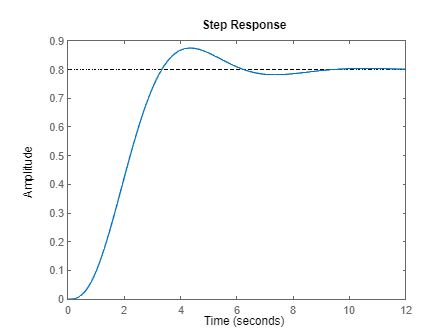

  step(Gs)

pade(0.1,5)
Gs

Gs =
 
               1
  ---------------------------
  s^3 + 2 s^2 + 2.25 s + 1.25
 
Continuous-time transfer function.



[Gs2_Licz,Gs2_Mian]=pade(0.5,3)

Gs2_Licz =     -1    24  -240   960


Gs2_Mian =      1    24   240   960


Gs2=tf(Gs2_Licz,Gs2_Mian)

Gs2 =
 
  -s^3 + 24 s^2 - 240 s + 960
  ---------------------------
  s^3 + 24 s^2 + 240 s + 960
 
Continuous-time transfer function.



Gs2=Gs*Gs2

Gs2 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



Gs2

Gs2 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



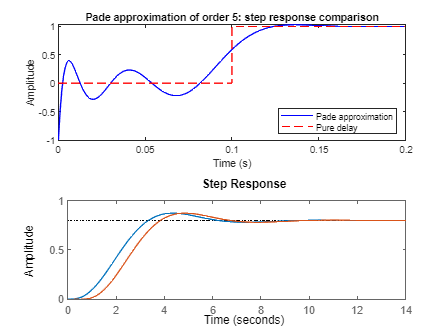

step(Gs,Gs2)

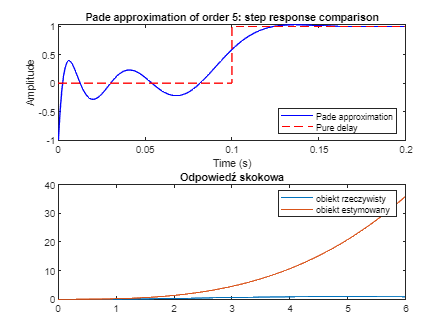

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           103145         
     1            5          93176.4         initial simplex
     2            6          93176.4         reflect
     3            7          93176.4         reflect
     4            9          87087.8         expand
     5           11          77374.8         expand
     6           12          77374.8         reflect
     7           14          66119.2         expand
     8           16            54763         expand
     9           17            54763         reflect
    10           19          41175.9         expand
    11           21          29066.5         expand
    12           22          29066.5         reflect
    13           24          19529.9         expand
    14           26          11218.4         expand
    15           27          11218.4         reflect
    16           29          6440.39         expand
    17           31           3121.1         expan

x =     6.6845   -5.7781   12.4918   -2.9623


fval = 0.2957

exitflag = 1



x0 = [1,0,0,0]; %

fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options)

%G1=tf([0 1],[1 2 2.25 1.25]);
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1],[x(1) x(2) x(3) x(4)])

G2 =
 
                     1
  ---------------------------------------
  6.684 s^3 - 5.778 s^2 + 12.49 s - 2.962
 
Continuous-time transfer function.



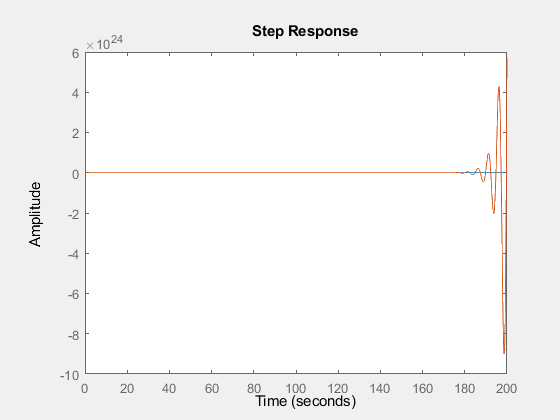

%step(G1);
step(G1,G2);


b=G2.Numerator{1, 1}

b =      0     0     0     1


a=G2.Denominator{1,1}

a =     6.6845   -5.7781   12.4918   -2.9623


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =    0.3028 + 1.2729i
   0.3028 - 1.2729i
   0.2589 + 0.0000i


k = 0.1496

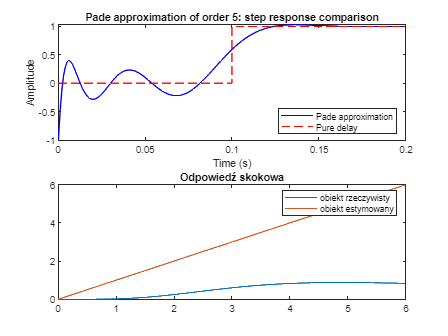

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          4950.97         
     1            5          4398.42         initial simplex
     2            6          4398.42         reflect
     3            8          4398.42         contract inside
     4            9          4398.42         reflect
     5           11          3973.94         expand
     6           13          3590.04         expand
     7           14          3590.04         reflect
     8           16          2956.61         expand
     9           18          2321.83         expand
    10           19          2321.83         reflect
    11           21          1704.22         expand
    12           23          1061.18         expand
    13           24          1061.18         reflect
    14           26          611.928         expand
    15           28          274.165         expand
    16           29          274.165         reflect
    17           31          96.9577     

x =     0.0061    0.0019    5.8370   -0.0164


fval = 7.1894

exitflag = 1



x0 = [0,0,1,0];
[x,fval,exitflag] = fminsearch(fun,x0,options)

%G1=tf([0 1],[1 2 2.25 1.25]);
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1],[x(1) x(2) x(3) x(4)])

G2 =
 
                         1
  -----------------------------------------------
  0.006127 s^3 + 0.001913 s^2 + 5.837 s - 0.01642
 
Continuous-time transfer function.



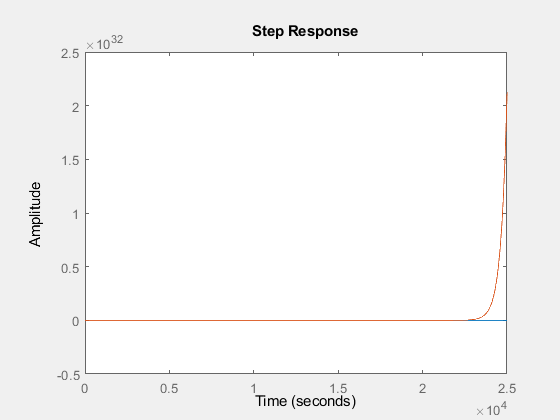

%step(G1);
step(G1,G2);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          85.2037         
     1            5          85.1963         initial simplex
     2            7          79.4508         expand
     3            8          79.4508         reflect
     4            9          79.4508         reflect
     5           11          73.6119         expand
     6           13          63.9316         expand
     7           14          63.9316         reflect
     8           16          51.8376         expand
     9           18          29.3023         expand
    10           19          29.3023         reflect
    11           21          17.7945         expand
    12           22          17.7945         reflect
    13           24          17.7945         contract inside
    14           25          17.7945         reflect
    15           27          17.7945         contract inside
    16           29          17.2455         contract inside
    17           30    

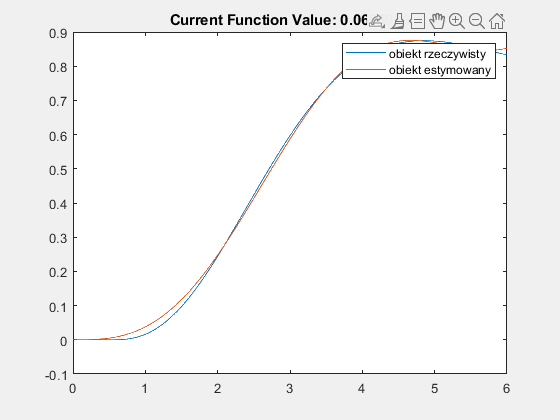

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x =     4.2248   -0.4809    6.1811   -0.0595


fval = 0.0687

exitflag = 1


x0 = [1,10,10,1];
[x,fval,exitflag] = fminsearch(fun,x0,options)

%G1=tf([0 1],[1 2 2.25 1.25]);
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1],[x(1) x(2) x(3) x(4)])

G2 =
 
                      1
  ------------------------------------------
  4.225 s^3 - 0.4809 s^2 + 6.181 s - 0.05948
 
Continuous-time transfer function.



%step(G1);

function blad = ident(x)
%K = X0(1);
%T = X0(2);
%n = X0(3);

%a1=x(1);
%b2=x(2);

t=0:0.01:6;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;


G2=tf([0 1],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

%---------------------------------------- ------%
% tutaj kod, który będzie obliczał
% odpowiedź skokową estymowanego modelu z optymalizacji
% o takiej samej długości jak odpowiedź
% obiektu rzeczywistego
plot(t, y1);
hold on;
plot(t, y2);
hold off;
legend(["obiekt rzeczywisty", "obiekt estymowany"])
title("Odpowiedź skokowa")
%---------------------------------------- ------%
e = y1-y2;
blad= sum(e.^2);
%blad= sum(e.^2) / length(e);
end